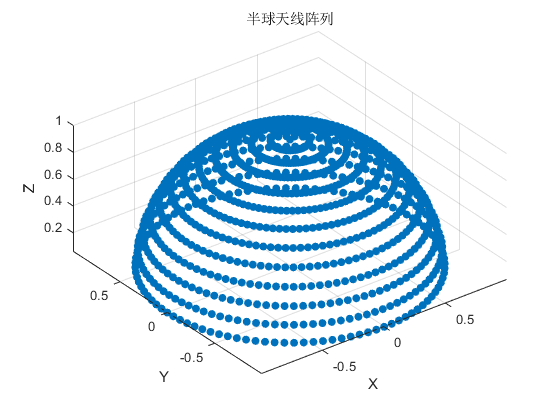

[theta, phi] = meshgrid(0:pi/25:pi/2, 0:pi/50:2*pi);
x = sin(theta) .* cos(phi);
y = sin(theta) .* sin(phi);
z = cos(theta);

% 绘制半球天线阵列
figure;
scatter3(x(:), y(:), z(:), 'filled');
xlabel('X');
ylabel('Y');
zlabel('Z');
title('半球天线阵列');
axis equal;

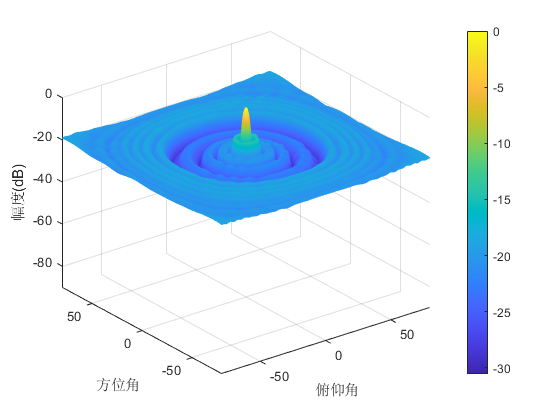


f0=3e9;
c=3e8;
lambda=c/f0; 
k=2*pi/lambda;

phi=0*pi/180;%目标方位角
theta=0*pi/180;%目标俯仰角

theta1=sin(phi)*cos(theta);
theta2=sin(theta);
theta3=cos(phi)*cos(theta);

X1=x(:);
Y1=y(:);
Z1=z(:);

steer_signal1=exp(1j*k*X1*theta1);
steer_signal2=exp(1j*(k*Y1*theta2));
steer_signal3=exp(1j*(k*Z1*theta3));
steer_signal4=steer_signal1.*steer_signal2.*steer_signal3;
normal_W=steer_signal4.';
%合成方向图
Theta =-80:0.1:80;
Phi =-80:0.1:80;
m = length (Theta);
n = length (Phi);
F = zeros (m,n);
for m =1:length(Theta)
    for n =1:length(Phi)
         theta =Theta(m); 
         phi = Phi(n);
         phase1 = exp(1j*k*X1*sin(theta*pi/180)*cos(phi*pi/180));
         phase2 = exp(1j*k*Y1*sin(phi*pi/180));
         phase3 = exp(1j*k*Z1*cos(theta*pi/180)*cos(phi*pi/180));
         phase_all = (phase1.*phase2.*phase3);
         F(m,n)=abs(((normal_W.')')*phase_all);
    end
end
FdB =20*log10(F/max(max(F)));%画增益图
figure 
mesh(Phi,Theta,FdB); 
colorbar 
xlabel ('俯仰角'); 
ylabel ('方位角'); 
zlabel ('幅度(dB)'); 
axis ([-80 80 -80 80 -90 0]);

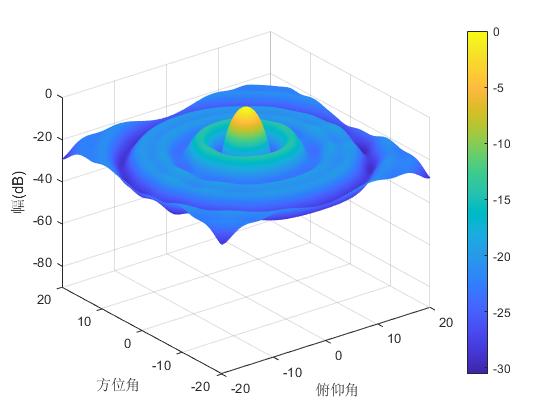

%画增益图放大
figure
mesh (Phi, Theta, FdB) ;
xlabel('俯仰角');ylabel( '方位角');zlabel( '幅(dB)');
  axis([-20 20 -20 20 -90 0]);
colorbar

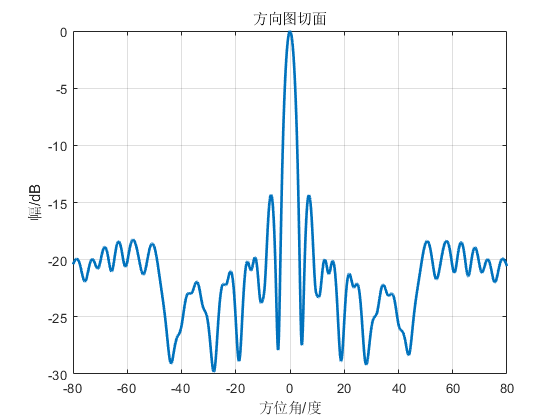

%画方位增益图
[ymax, iy]=max(max(FdB)); 
figure
plot (Theta,FdB(:,iy),'linewidth',2);title('方向图切面');
xlabel('方位角/度');ylabel( '幅/dB')
grid on;
hold on

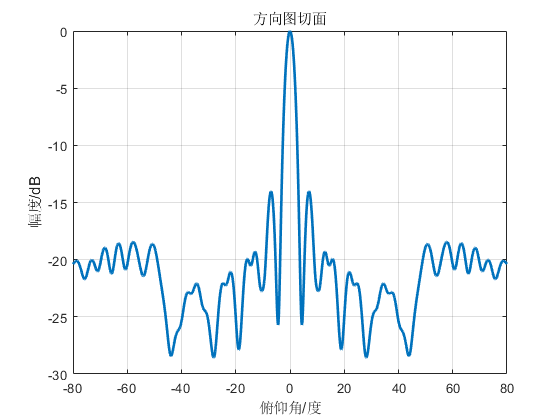

%画俯仰增益图
[xnax,ix]=max(FdB(:,iy));
figure
plot(Phi,FdB(ix, :),'linewidth',2);title('方向图切面');
xlabel( '俯仰角/度');ylabel( '幅度/dB');grid on;hold on;

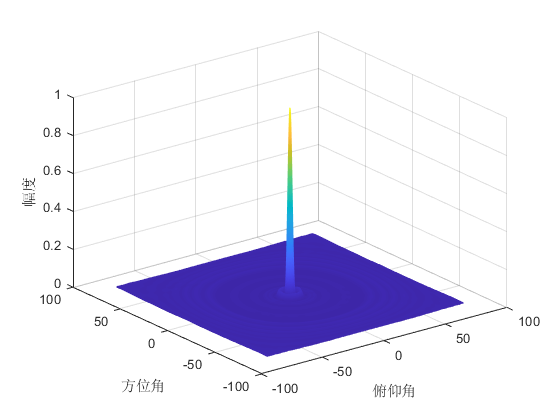

%画方位原始数值增益
figure
mesh(Phi, Theta, 10.^(FdB/10));
xlabel( '俯仰角');ylabel( '方位角');zlabel( '幅度')